clear
lines = readlines("ANON_19810211.GDT");
testing= false;
for c = 1:lines.size
    currentLine = lines(c);
    if currentLine.contains("Time") && currentLine.contains("Load")
        testing = true;
        testStart= c
    end
    if currentLine.contains("***") && testing== true
        testEnd = c
        testing = false;
    end
end

testStart = 110

testEnd = 214

for j=1:(testEnd-testStart)
    testLines(j,1)=lines(j+testStart-1);
end
testTable=zeros(13);
for i=1:testLines.size(1)
    splitLine=transpose(split(testLines(i)));
    lineLenght = splitLine.size;
    splitLine=cat(2,splitLine,zeros(1,(13-lineLenght(2))));
    testTable(i,:)= splitLine;
end

testTable(1,:)=[];
testTable(1,:)=[];
testTable(:,2)=[];
isNan=isnan(testTable(:,2))

isNan = 102×1 logical array
   1
   0
   0
   0
   0
   0
   1
   0
   0
   0


for j=size(testTable,1):-1:1
    if sum(isNan(j))>=1
        j
        testTable(j,:)=[];
    end
end

j = 82

j = 73

j = 33

j = 7

j = 1

testTable(:,1)=transpose(0:10:10*size(testTable,1)-1);
testTable

testTable =          0         0   78.0000    6.3000    4.6400   19.0000   28.0000   23.9000   32.7000    0.7300    8.1000       NaN
   10.0000         0   74.0000    4.7000    3.8200   18.0000   21.1000   32.6000   40.1000    0.8100    6.3000       NaN
   20.0000         0   74.0000    4.1000    3.5100   17.0000   21.2000   34.7000   40.9000    0.8500    5.6000       NaN
   30.0000         0   74.0000    2.9000    2.5500   13.0000   19.2000   36.3000   41.5000    0.8700    3.9000       NaN
   40.0000         0   74.0000    2.2000    1.9300   11.0000   19.0000   37.5000   43.5000    0.8600    3.0000   33.0000
   50.0000         0   76.0000    3.7000    2.9300   14.0000   20.2000   29.5000   37.8000    0.7800    4.9000   33.0000
   60.0000   20.0000   75.0000    8.0000    6.6200   25.0000   17.0000   27.8000   33.5000    0.8300   10.6000   33.0000
   70.0000   20.0000   71.0000    6.8000    6.2100   23.0000   17.2000   30.9000   33.6000    0.9200    9.5000   33.0000
   80.0000   20.0000

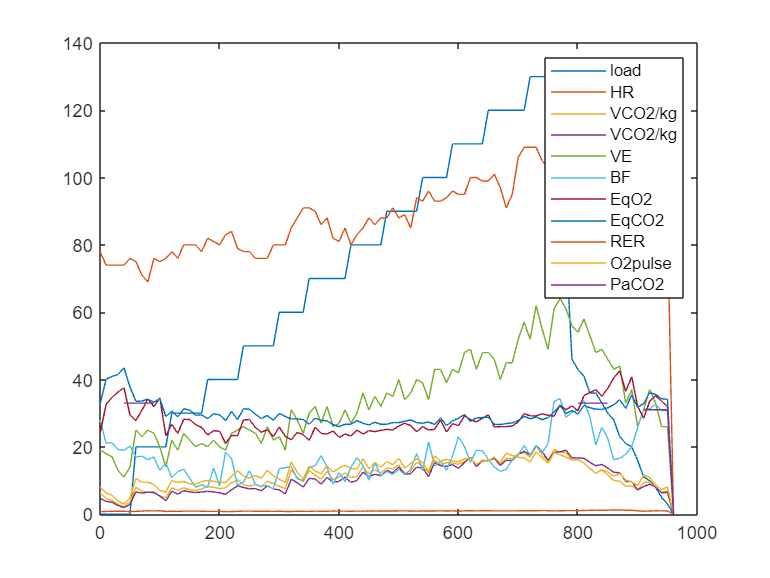

plot(testTable(:,1),testTable(:,2))
hold on
plot(testTable(:,1),testTable(:,3))
plot(testTable(:,1),testTable(:,4))
plot(testTable(:,1),testTable(:,5))
plot(testTable(:,1),testTable(:,6))
plot(testTable(:,1),testTable(:,7))
plot(testTable(:,1),testTable(:,8))
plot(testTable(:,1),testTable(:,9))
plot(testTable(:,1),testTable(:,10))
plot(testTable(:,1),testTable(:,11))
plot(testTable(:,1),testTable(:,12))
legend('load','HR','VCO2/kg','VCO2/kg','VE','BF','EqO2','EqCO2','RER','O2pulse','PaCO2')